%Modulation Order of QAM
M = 16;

%Number of Bits per Symbol
symBitSize = log2(M);

%Number of Iterations for Experimentation
nIter = 200;

%Number of Symbols to be sent in each Iteration
nSymbols = 10000;

%Total Number of Symbols sent for each SNR value
totalSymbols = nIter*nSymbols;

%Number of Bits in Input Binary Signal
nBits = nSymbols*symBitSize;

%Defining SNR values (dB)
SNRdB = 0:15;

%Calculating SNR values (Linear)
SNR = 10.^(SNRdB/10);

%Calculating Noise Amplitude Values as per SNR values
noiseAmp = 1./SNR;

%Calculating Theoretical BER values
ThBER = (1/symBitSize)*(3/2)*erfc(sqrt(symBitSize*0.1*SNR));

%Symbols array
symbolSpace = 0:15;

%Binary coded Modulated Symbols
symbolSpaceB = QAMBinModulator(symbolSpace, M);

%Gray coded Modulated Symbols
symbolSpaceG = QAMGrayModulator(symbolSpace, M);

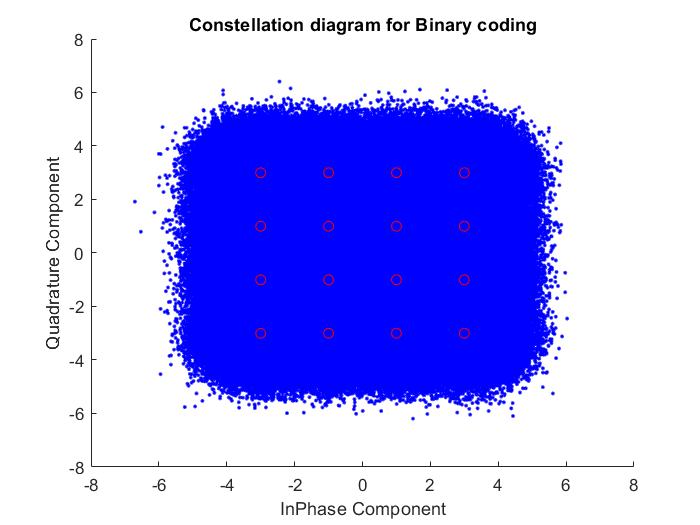

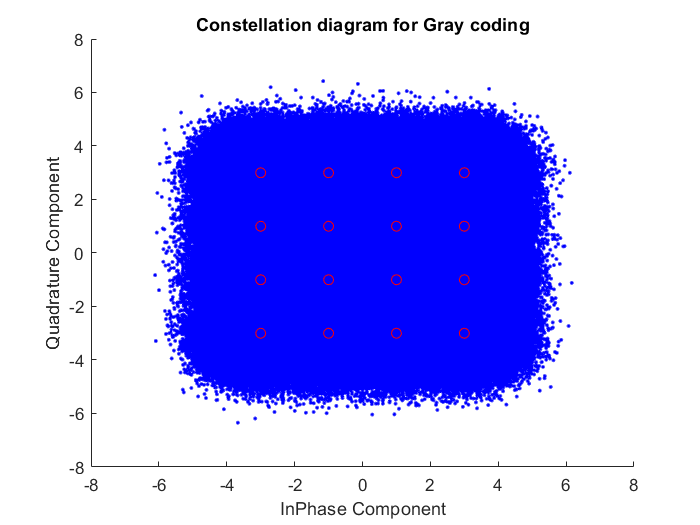

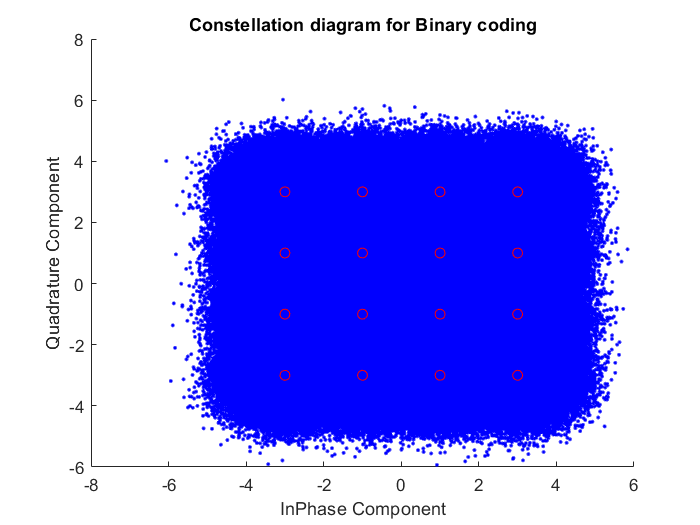

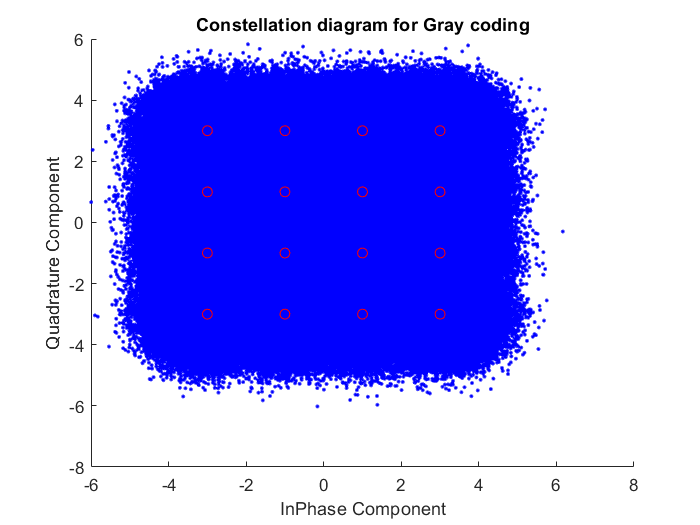

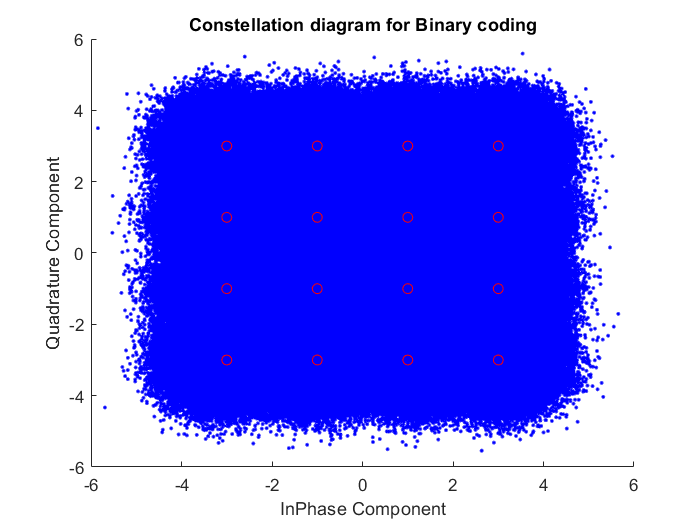

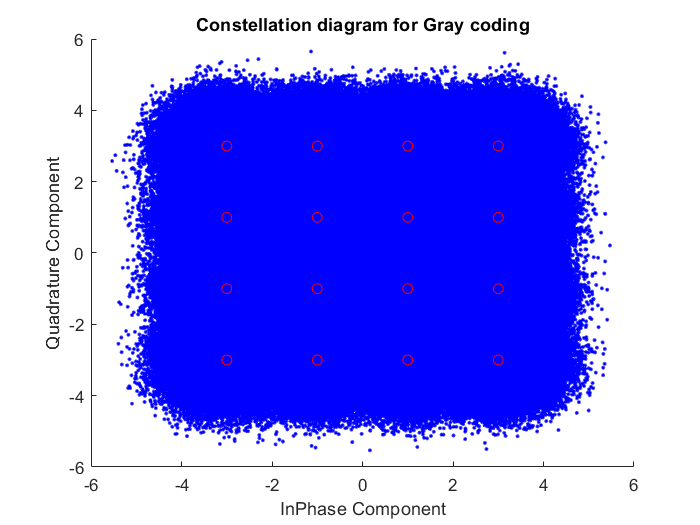

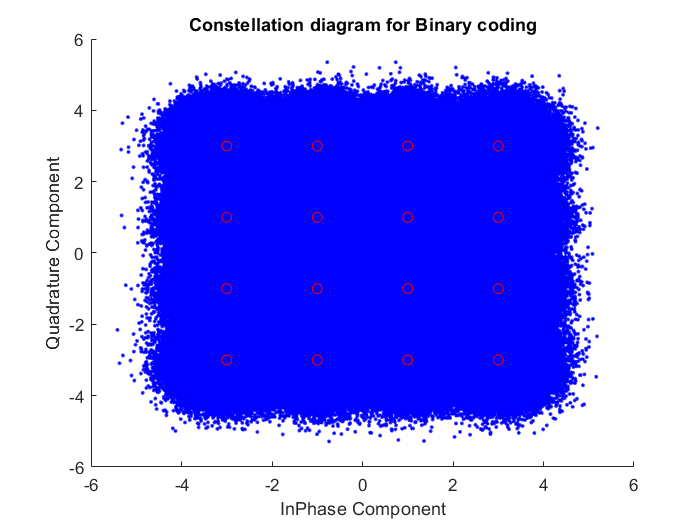

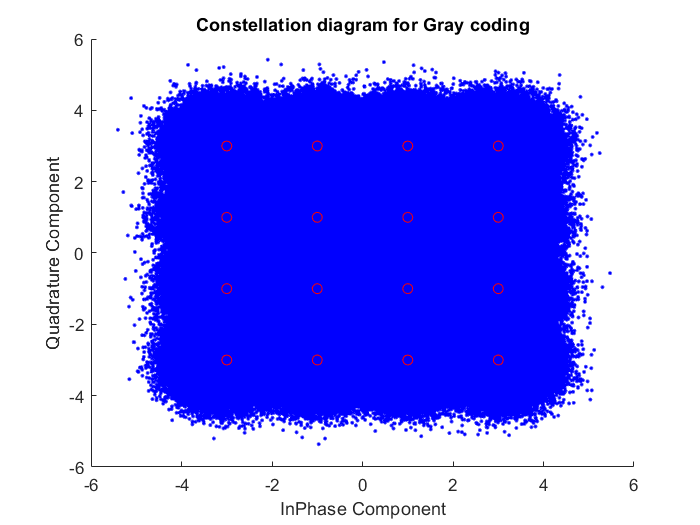

%Defining Container for Simulated BER for Binary Coding
SimBERbin = zeros(length(SNRdB), 1);

%Defining Container for Simulated BER for Gray Coding
SimBERgray = zeros(length(SNRdB), 1);

%Loop for Simulation
for SNRindex = 1:length(SNR)
    
    %Defining container for noisy signal values
    channelSigGpoints = zeros(totalSymbols, 1);
    channelSigBpoints = zeros(totalSymbols, 1);
    
    %For an SNR value, total error bits from all simulation will be saved
    %in these variables
    totalBERbin = 0;
    totalBERgray = 0;
    
    %Iterating the results for same SNR value
    for iter = 1:nIter
    
        %Generating Random Input Binay Signal
        inBinSig = randi([0 1], nBits, 1);
        
        %Grouping 4 Consecutive Bits for Symbol Generation
        inBinGroupedSig = reshape(inBinSig, nSymbols, symBitSize);
        
        %Container for Input Symbolic Signal
        inSymSig = zeros(nSymbols, 1);
        
        %Generating Input Symbolic Signal as per generated Input Binary Signal
        for index = 1:nSymbols
            inSymSig(index) = polyval(inBinGroupedSig(index, :), 2);
        end
        
        %Using Binary Coding
        
        %Generating Modulated Signal
        modSigB = QAMBinModulator(inSymSig, M);
        
        %Adding AWGN Noise according to Current SNR value
        channelSigB = modSigB + sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1) + 1i*sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1);
        
        %Calculating Demodulated Signal
        demodSigB = QAMBinDemodulator(channelSigB, M);
        
        %Calculating total error bits till current iteration
        totalBERbin = totalBERbin + sum(demodSigB ~= inSymSig);
        
        %Using Gray Coding
        
        %Generating Modulated Signal
        modSigG = QAMGrayModulator(inSymSig, M);
        
        %Adding AWGN Noise according to Current SNR value
        channelSigG = modSigG + sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1) + 1i*sqrt(noiseAmp(SNRindex)/2)*randn(nSymbols, 1);
        
        %Calculating Demodulated Signal
        demodSigG = QAMGrayDemodulator(channelSigG, M);
        
        %Calculating total error bits till current iteration
        totalBERgray = totalBERgray + sum(demodSigG ~= inSymSig);
        
        %Calculating the index values to save noisy signal values in above
        %declared containers
        startIndex = 1 + (iter - 1)*nSymbols;
        endIndex = iter*nSymbols;
        
        %Storing the noisy signal values in the respective index range
        channelSigBpoints(startIndex:endIndex) = channelSigB;
        channelSigGpoints(startIndex:endIndex) = channelSigG;
        
    end
    
    %Calculating Simulated BER for current SNR value
    SimBERbin(SNRindex) = totalBERbin/totalSymbols;
    SimBERgray(SNRindex) = totalBERgray/totalSymbols;
    
    %Plotting constellation diagrams for SNR values
    figure(2*SNRindex-1);
    scatter(real(channelSigBpoints), imag(channelSigBpoints), 'b.');
    hold on;
    scatter(real(symbolSpaceB), imag(symbolSpaceB), 'red');
    hold off;
    title('Constellation diagram for Binary coding');
    xlabel('InPhase Component');
    ylabel('Quadrature Component');
    
    figure(2*SNRindex);
    scatter(real(channelSigGpoints), imag(channelSigGpoints), 'b.');
    hold on;
    scatter(real(symbolSpaceG), imag(symbolSpaceG), 'red');
    hold off;
    title('Constellation diagram for Gray coding');
        xlabel('InPhase Component');
    ylabel('Quadrature Component');
    
end

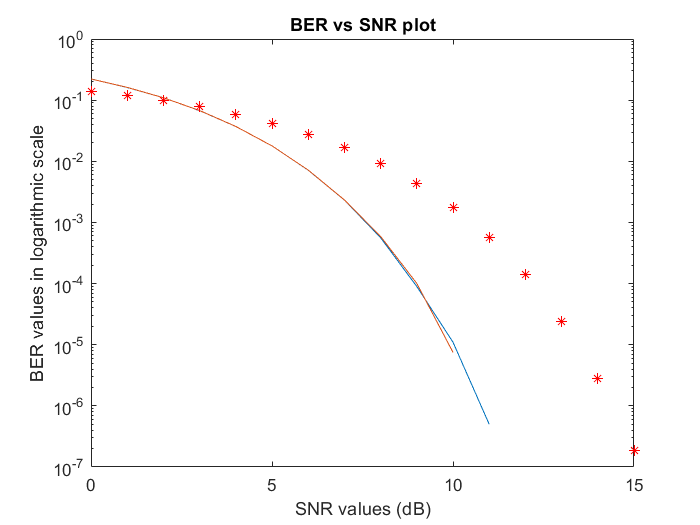

%Plotting BER curves
figure(2*SNRindex+1);
semilogy(SNRdB, SimBERgray); %Gray coded Simulation
hold on;
semilogy(SNRdB, SimBERbin); %Binary coded Simulation
hold on;
semilogy(SNRdB, ThBER, 'r*'); %Theoretical BER
hold off;
xlabel('SNR values (dB)');
ylabel('BER values in logarithmic scale')
title('BER vs SNR plot');